clear;
clf;
% Code to convert data output by FreeFem++ to matlab readable data
% Using the ffmatlib library
% https://github.com/samplemaker/freefem_matlab_octave_plot

filePrefix = {'HPMovie15','HPMovie30','HPMovie60','HPMovie90','HPMovie120'};

addpath('ffmatlib');
[p15,b15,t15]=ffreadmesh(strcat(filePrefix{1},'.msh'));
[p30,b30,t30]=ffreadmesh(strcat(filePrefix{2},'.msh'));
[p60,b60,t60]=ffreadmesh(strcat(filePrefix{3},'.msh'));
[p90,b90,t90]=ffreadmesh(strcat(filePrefix{4},'.msh'));
[p120,b120,t120]=ffreadmesh(strcat(filePrefix{5},'.msh'));
vh15=ffreaddata(strcat(filePrefix{1},'Vh.txt'));
vh30=ffreaddata(strcat(filePrefix{2},'Vh.txt'));
vh60=ffreaddata(strcat(filePrefix{3},'Vh.txt'));
vh90=ffreaddata(strcat(filePrefix{4},'Vh.txt'));
vh120=ffreaddata(strcat(filePrefix{5},'Vh.txt'));

totalFrames = 11;
for j = 0:totalFrames-1
    u15(:,j+1) = ffreaddata(sprintf('HPMovie15%i.txt', j));
    u30(:,j+1) = ffreaddata(sprintf('HPMovie30%i.txt', j));
    u60(:,j+1) = ffreaddata(sprintf('HPMovie60%i.txt', j));
    u90(:,j+1) = ffreaddata(sprintf('HPMovie90%i.txt', j));
    u120(:,j+1) = ffreaddata(sprintf('HPMovie120%i.txt', j));
end

% Interpolate the snapshot for points other than the triangulation points
% To compare with an equispaced grid generated by linspace(...)

x = linspace(-2,2,100);
y = linspace(-2,2,100);
[XX,YY] = meshgrid(x,y);

% Store interpolated data for each resolution
for i = 1:totalFrames
    U15(:,:,i) = ffinterpolate(p15,b15,t15,vh15,XX,YY,u15(:,i))';
    U30(:,:,i) = ffinterpolate(p30,b30,t30,vh30,XX,YY,u30(:,i))';
    U60(:,:,i) = ffinterpolate(p60,b60,t60,vh60,XX,YY,u60(:,i))';
    U90(:,:,i) = ffinterpolate(p90,b90,t90,vh90,XX,YY,u90(:,i))';
    U120(:,:,i) = ffinterpolate(p120,b120,t120,vh120,XX,YY,u120(:,i))';
end

Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


% Testing for convergence by testing by how much each approximation
% at time t=1 changes as we increase the resolution.
% Should the approximations change less between larger
% resolutions, we take this as experimental evidence that
% the approximation is converging.

% Cleaning up data for time t=1
U15t1 = U15(:,:,11);
U30t1 = U30(:,:,11);
U60t1 = U60(:,:,11);
U90t1 = U90(:,:,11);
U120t1 = U120(:,:,11);

% Removing NaN and replacing with 0
U15t1(isnan(U15(:,:,11)))=0;
U30t1(isnan(U30(:,:,11)))=0;
U60t1(isnan(U60(:,:,11)))=0;
U90t1(isnan(U90(:,:,11)))=0;
U120t1(isnan(U120(:,:,11)))=0;

% Maximum difference for values interpolated on at time t=1
max(abs(U15t1 - U30t1),[],'all')

ans = 0.0306

max(abs(U30t1 - U60t1),[],'all')

ans = 0.0197

max(abs(U60t1 - U90t1),[],'all')

ans = 0.0088

max(abs(U90t1 - U120t1),[],'all')

ans = 0.0051


% Average difference for values interpolated on at time t=1
sum(abs(U15t1 - U30t1))/sum(U15t1~=0)

ans = 0.0025

sum(abs(U30t1 - U60t1))/sum(U30t1~=0)

ans = 0.0012

sum(abs(U60t1 - U90t1))/sum(U60t1~=0)

ans = 4.6632e-04

ans = 2.6388e-04

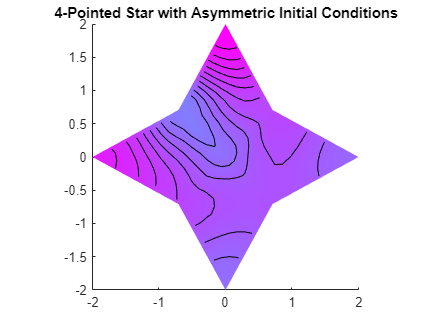

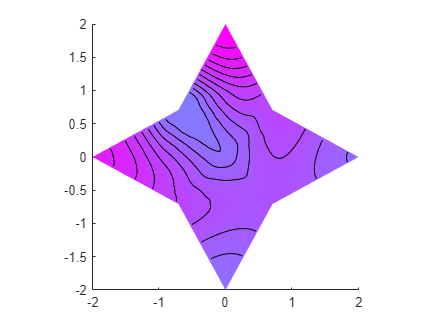

Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


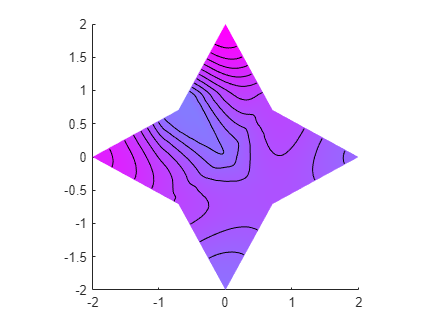

Note: To improve runtime build MEX function fftri2gridfast() from fftri2gridfast.c


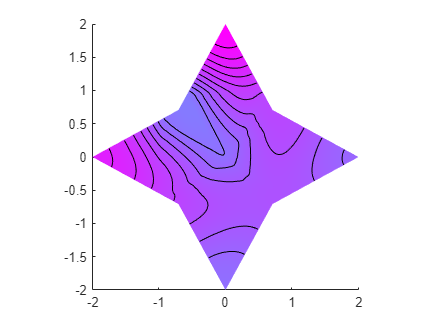

sum(abs(U90t1 - U120t1))/sum(U90t1~=0)